## **CBM-Toolbox Script for Reversal Learning Data**

This script fits reinforcement learning models to choice data from reversal learning using the Computational Behavioral Modeling toolbox by [Piray et al., 2019](https://journals.plos.org/ploscompbiol/article?id=10.1371/journal.pcbi.1007043)  that applies hierarchical Bayesian inference during concurrent model fitting. In order to run successfully, you need add the cbm-toolbox ('codes') to your matlab-path, and have the 'model_RL' script in the Reversal_Vol_CBM folder. The model script contains a standard Rescorla Wagner model-space with Single Update, individually weighted Double Update and full Double update, with one or two learning rates (win/loss), combined with a softmax (1 beta).    

## **1) Prepare data for cbm**

adapt the paths for your computer

clc 
clear all
close;
TK = 1;
if TK 
cd('/Users/katthagt/Owncloud/Shared/Reversal_Vol');
addpath('C:\Users\katthagt\ownCloud\Shared\Reversal_Vol\scripts_cbm'); % adapt
input_path = '/Users/katthagt/Owncloud/Shared/Reversal_Vol/data/T1/'; %behavioral data in mat files, adapt for T1 / T2
else    
cd('/Users/larawieland/Owncloud/Shared/Reversal_Vol');
% addpath('/Users/larawieland/Documents/ECN/Promotion/Modeling/cbm/codes'); % adapt
% addpath('C:\Users\katthagt\ownCloud\Shared\NegSym\Modeling\hgfToolBox_v4.15');
input_path = '/Users/larawieland/Owncloud/Shared/Reversal_Vol/data/T1/'; %behavioral data in mat files, adapt for T1 / T2
end

% load data
input =  dir([input_path, '*WS.mat']);
data = {};
nmodels = 6;
nsubjects = length(input);

% subject loop to store all individual choice data in cohensive input file needed for cbm
for sub = 1:length(input)
data{sub,1}.code   = input(sub).name(12:19);
data{sub,1}.T      = input(sub).name(18:19);
load([input_path input(sub).name], 'R', 'A');
R = R(~isnan(A));  A = A(~isnan(A)); R(R==-1)=0; %check whether your model needs losses as 0 or -1
data{sub,1}.actions = A;
data{sub,1}.outcome = R;
end

## 2) check if model is running correctly with random parameters (no actual fitting)

Note: The cbm files were modified, so that one learning script can fit different models depending on the model number, that is the third input now in the standard fitting function loglik = model_RL(parameters,subj, model_no). Check section 3 for amount of free parameters for each model.

Model numbers (model_no):

1 --> SU 1 alpha, 2 --> SU 2 alphas

3 --> iDU 1 alpha, 2 --> iDU 2 alphas

4 --> DU 1 alpha, 2 --> DU 2 alphas 

% loglik = model_RL(parameters,subj1)

subj1 = data{1}; 
parameters = randn(1,3); 
% F1 = model_RL(parameters,subj1,2),
[F1, traj] = model_RL_DU2al(parameters,subj1)

% 
% figure
% hold on
% plot(outcome+0.05, '.')
% plot(actions-1, '.')
% plot(q)

## 3) use cbm for initial model fitting and group prior estimation 

The function 'cbm_lap' fits every model to each subject data separately (i.e. in a non-hierarchical fashion, so that only (random) individuals are fitted first without any (fixed) group information)

It uses Laplace approximation needing a normal prior for every parameter ([see manual](file:///C:/Users/katthagt/ownCloud/cbm-master/manual.html)) with: 

mean = 0 and variance = 6.25. 

All parameters are normalized (-Inf to Inf), thus parameters between 0:1 need to be sigmoid-transformed (--> logit-space) and parameters > 0 must be exponential-transformed (log-space) in the beginning of the learning model-file.

crucial function: cbm_lap(data, @model, priors, output file,[ ], model_no)

v                = 6.25;    % variance is the same for all priors
% name output files
fname_RL = {};
fname_RL{1}='SU1al_T1.mat';  fname_RL{2}='SU2al_T1.mat'; fname_RL{3}='iDU1al_T1.mat'; 
fname_RL{4}='iDU2al_T1.mat'; fname_RL{5}='DU1al_T1.mat'; fname_RL{6}='DU2al_T1.mat'; 

% set amount of priors for each model
prior(1)     = struct('mean', zeros(2,1),'variance',v);          % 2 free parameters (alpha, beta)
prior(2)     = struct('mean', zeros(3,1),'variance',v);          % 3 free parameters (alpha_rew, alpha_pun, beta) 
prior(3)     = struct('mean', zeros(3,1),'variance',v);          % 3 free parameters (alpha, kappa, beta)
prior(4)     = struct('mean', zeros(4,1),'variance',v);          % 4 free parameters (alpha_rew, alpha_pun, kappa, beta) 
prior(5)     = struct('mean', zeros(2,1),'variance',v);          % 2 free parameters (alpha, beta)
prior(6)     = struct('mean', zeros(3,1),'variance',v);          % 3 free parameters (alpha_rew, alpha_pun, beta) 

models = {'@model_RL_SU1al', '@model_RL_SU2al','@model_RL_iDU1al', '@model_RL_iDU2al','@model_RL_DU1al', '@model_RL_DU2al'};

cbm_lap(data, @model_RL_SU1al,  prior(1), char(fname_RL(1))); % last input for model number!

cbm_lap                                           23-Apr-2020 15:04:00
Number of samples: 46
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
done :]


cbm_lap(data, @model_RL_SU2al,  prior(2), char(fname_RL(2))); % last input for model number!

cbm_lap                                           23-Apr-2020 15:04:07
Number of samples: 46
Number of parameters: 3

Number of initializations: 21
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
done :]


cbm_lap(data, @model_RL_iDU1al, prior(3), char(fname_RL(3))); % last input for model number!

cbm_lap                                           23-Apr-2020 15:04:19
Number of samples: 46
Number of parameters: 3

Number of initializations: 21
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
done :]


cbm_lap(data, @model_RL_iDU2al, prior(4), char(fname_RL(4)));% last input for model number!

cbm_lap                                           23-Apr-2020 15:04:42
Number of samples: 46
Number of parameters: 4

Number of initializations: 28
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
done :]


cbm_lap(data, @model_RL_DU1al,  prior(5), char(fname_RL(5))); % last input for model number!

cbm_lap                                           23-Apr-2020 15:05:37
Number of samples: 46
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
done :]


cbm_lap(data, @model_RL_DU2al,  prior(6), char(fname_RL(6))); % last input for model number!

cbm_lap                                           23-Apr-2020 15:05:50
Number of samples: 46
Number of parameters: 3

Number of initializations: 21
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
done :]


## 5) hierarchical Bayesian inference: concurrent model fitting

Here, we use the parameters from step 3 as priors for concurrent model-fitting (all models are fitted within one step). Using hierarchical bayesian inference, random (individuals') parameters inform the fixed (group) parameters according to the likelihood of this model being the best model for the respective subject ("responsibility"). 

Central function: cbm_hbi(data,nmodels,fcbm_maps,fname_hbi);

% 2nd input: a cell input containing function handle to models (== @ before the name of the function)
models = {@model_RL_SU1al, @model_RL_SU2al, @model_RL_iDU1al, @model_RL_iDU2al, @model_RL_DU1al, @model_RL_DU2al};

% 3rd input: another cell input containing file-address to files saved by
% cbm_lap, note that they corresponds to models (so pay attention to the order)
fcbm_maps = {'SU1al_T1.mat','SU2al_T1.mat','iDU1al_T1.mat','iDU2al_T1.mat','DU1al_T1.mat','DU2al_T1.mat'};

% 4th input: a file address for saving the output
fname_hbi = 'hbi_RL_fullmodelspace_T1.mat';

cbm_hbi(data,models,fcbm_maps,fname_hbi);

cbm_hbi_hbi                                       23-Apr-2020 15:06:39
Running hierarchical bayesian inference (HBI)...

HBI has been initialized according to
	SU1al_T1.mat [for model 1]
	SU2al_T1.mat [for model 2]
	iDU1al_T1.mat [for model 3]
	iDU2al_T1.mat [for model 4]
	DU1al_T1.mat [for model 5]
	DU2al_T1.mat [for model 6]
 
Number of samples: 46
Number of models: 6
Iteration 01
Iteration 02
	model frequencies (percent)
	model 1: 19.2| model 2: 15.0| model 3: 23.8| model 4: 22.3| model 5: 11.8| model 6: 8.0| 
                                                           dL:   41.94
                                                           dm:   76.20
                                                           dx:    0.54
Iteration 03
	model frequencies (percent)
	model 1: 19.2| model 2: 11.2| model 3: 31.1| model 4: 26.8| model 5: 8.3| model 6: 3.5| 
                                                           dL:   

## 6) Plot the hbi parameters

As in step 4, display the fitted parameters as implemented in the toolbox function: 'cbm_hbi_plot(fname_hbi, model_names, param_names, transform, model of interest)'

1st input is the file-address of the file saved by cbm_hbi

2nd input: a cell input containing model names

3rd input: another cell input containing parameter names of the winning model 

4th input: another cell input containing transformation function associated with each parameter of the winning model

5th input: optional, indicates model of interest

fname_hbi = 'hbi_RL_fullmodelspace_T1.mat'; % 1st input is the file-address of the file saved by cbm_hbi
hbi = load('hbi_RL_fullmodelspace_T1.mat');
cbm = hbi.cbm;
cbm.output 

ans = struct with fields:
                     parameters: {6×1 cell}
                 responsibility: [46×6 double]
                     group_mean: {[0.5177 1.5952]  [1.6015e-06 9.1113e-07 9.3304e-06]  [0.0845 -1.8932 1.7065]  [6.0412e-06 6.0467e-06 3.4461e-06 2.0128e-05]  [0.1711 0.3548]  [1.3065e-04 1.3065e-04 5.2876e-04]}
    group_hierarchical_errorbar: {[0.1543 0.2633]  [0.1414 0.1414 0.1414]  [0.0412 0.1168 0.0847]  [0.1414 0.1414 0.1414 0.1414]  [0.1292 0.1836]  [0.1412 0.1412 0.1414]}
                model_frequency: [0.1734 1.0283e-06 0.7843 3.0950e-06 0.0422 8.1075e-05]
                exceedance_prob: [9.0000e-06 0 1.0000 0 0 0]
      protected_exceedance_prob: [8.0000e-06 2.2680e-50 1.0000 2.2680e-50 2.2680e-50 2.2680e-50]


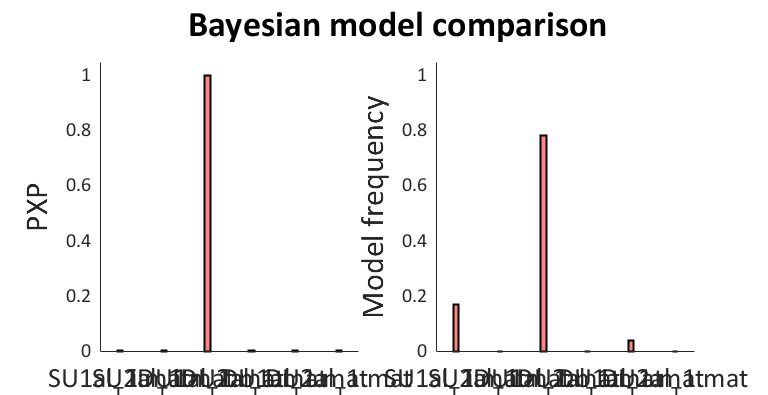

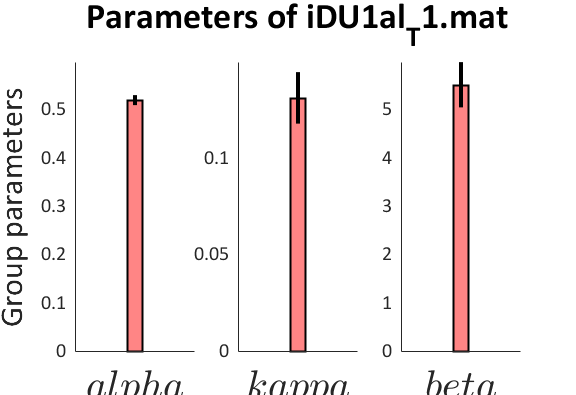


[M,I]=max(cbm.output.exceedance_prob);   % find the model with the highest exceedance probability index I

param_names(1).p        = {'alpha', 'beta'};
param_names(1).transform= {'sigmoid', 'exp'};
param_names(2).p        = {'alpha reward', 'alpha loss', 'beta'};
param_names(2).transform= {'sigmoid', 'sigmoid', 'exp'};
param_names(3).p        = {'alpha', 'kappa', 'beta'};
param_names(3).transform= {'sigmoid', 'sigmoid', 'exp'};
param_names(4).p        = {'alpha reward', 'alpha loss', 'kappa', 'beta'};
param_names(4).transform= {'sigmoid','sigmoid','sigmoid','exp'};
param_names(5)   = param_names(1);
param_names(6)   = param_names(2);

cbm_hbi_plot(fname_hbi, fname_RL, param_names(I).p, param_names(I).transform, I) % this function creates a model comparison plot (exceednace probability and model frequency) as well as

## 4) Check the fitted parameters

Note that the parameters are normalized before saving, and not to be back-transformed to make sense in the model. 

params contains all fitted parameters (subjects, parameters, model_no):

1st column: alpha_both     2nd alpha_reward     3rd alpha_loss    4th kappa     5th beta 

You can pick between the parameters from the individually fitted models and the ones from hierarchical Bayesian inference with "whichfit" 

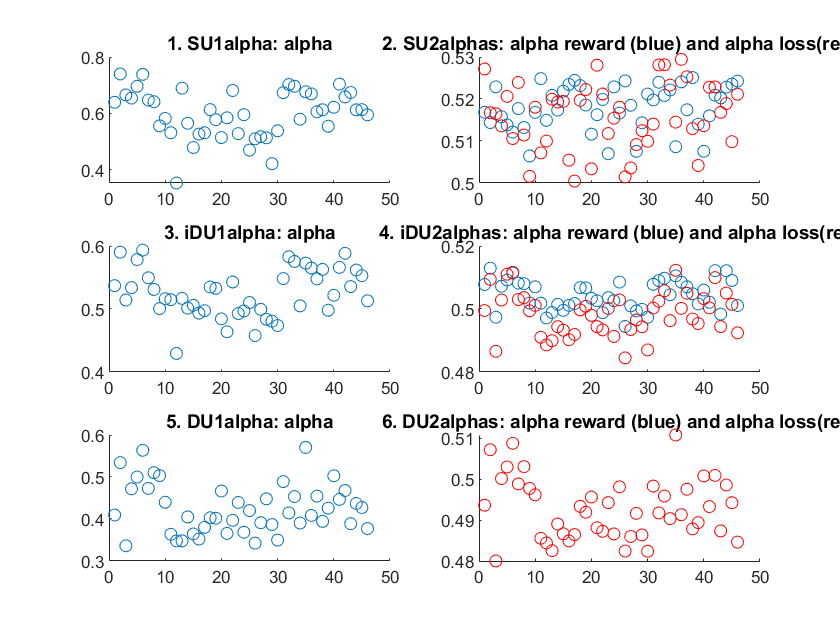

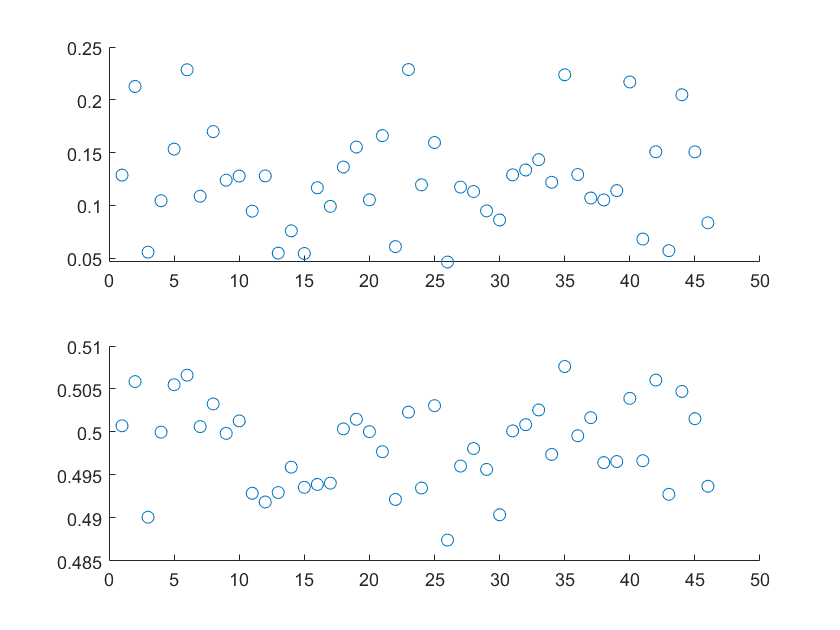

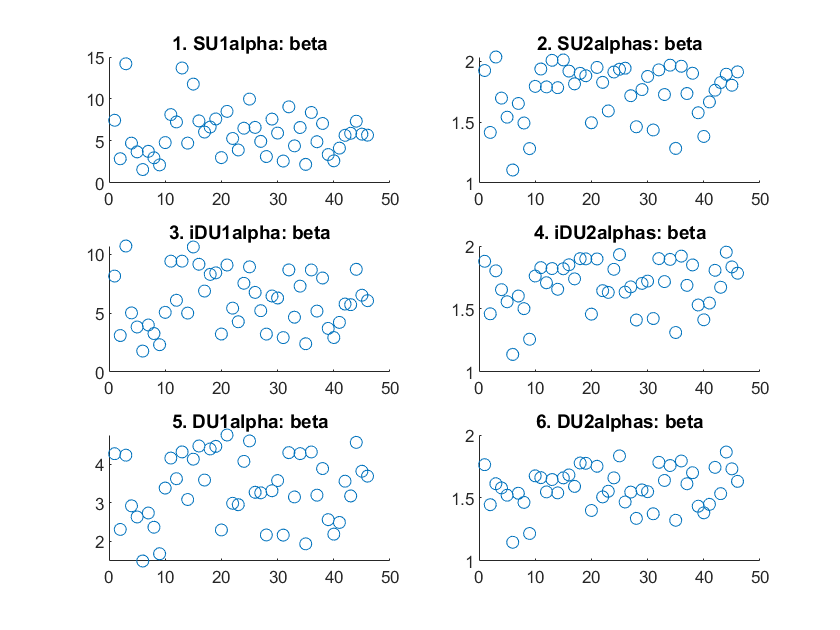

params = NaN(nsubjects, 6, nmodels);
whichfit = 2; % for cbm, 2 for hbi
 
if whichfit == 2
     fname_hbi = load('hbi_RL_fullmodelspace_T1.mat');
     cbm = fname_hbi.cbm;
end

for i = 1:nmodels
if whichfit == 1
    model_name = load(fname_RL{i});
    cbm = model_name.cbm;
    nd_params = cbm.output.parameters;
else
    nd_params = cbm.output.parameters{i};
    params(:,6,i) = cbm.output.responsibility(:,i);
end
        
if mod(i,2)
params(:,1,i)= 1./(1+exp(-nd_params(:,1)));  % alpha
    if (i == 1 | i == 5)
params(:,5,i)= exp(nd_params(:,2));     % beta
    elseif i==3
params(:,4,i)= 1./(1+exp(-nd_params(:,2))); % kappa
params(:,5,i)= exp(nd_params(:,3));        % beta
    end
elseif ~mod(i,2)
params(:,2:3,i)= 1./(1+exp(-nd_params(:,1:2))); % alpha_win, alpha_loss
    if (i == 2 | i == 6)
params(:,5,i)= exp(nd_params(:,3));     % beta
    elseif i==4
params(:,4,i)= 1./(1+exp(-nd_params(:,3))); % kappa
params(:,5,i)= exp(nd_params(:,4));        % beta
    end
end
clear nd_params
end

% % Plot parameters

for i = 1:3     %number of max free parameters
figure; hold on;
if i == 1       % alpha   
for j = 1:nmodels 
    subplot(3,2,j);
    if mod(j,2)
    scatter((1:nsubjects),params(:,1,j));
    else
    scatter((1:nsubjects),params(:,2,j)); hold on;
    scatter((1:nsubjects),params(:,3,j), 'r'); hold off;    
    end
    if j==1
    title('1. SU1alpha: alpha');
    elseif j==2
    title('2. SU2alphas: alpha reward (blue) and alpha loss(red)');
    elseif j==3
    title('3. iDU1alpha: alpha');
    elseif j==4
    title('4. iDU2alphas: alpha reward (blue) and alpha loss(red)');
    elseif j==5
    title('5. DU1alpha: alpha');
    elseif j==6
    title('6. DU2alphas: alpha reward (blue) and alpha loss(red)');
    end
    
end
elseif i ==2 % kappa
for j = 1:nmodels 
    if j==3
    subplot(2,1,1)
    title('3. iDU1alpha: kappa');
    scatter((1:nsubjects),params(:,4,j));
    elseif j==4
    subplot(2,1,2)
    title('4. iDU2alphas: kappa'); 
    scatter((1:nsubjects), params(:,4,j));
    end
end
    
elseif i ==3 % beta
    for j = 1:nmodels   
    subplot(3,2,j);
        scatter((1:nsubjects), params(:,5,j));
        if j==1
        title('1. SU1alpha: beta');
        elseif j==2
        title('2. SU2alphas: beta');
        elseif j==3
        title('3. iDU1alpha: beta');
        elseif j==4
        title('4. iDU2alphas: beta');
        elseif j==5
        title('5. DU1alpha: beta');
        elseif j==6
        title('6. DU2alphas: beta');
        end
    end
end    
    hold off;
end

## 5. Compare group parameters and model comparison

hold off; figure 
parameters_RL = cbm.output.parameters{1};
parameters_dualRL = cbm.output.parameters{2};
responsibility = cbm.output.responsibility;
plot(responsibility(:,2)); ylim([-.1 1.1]);

% estimate protected exceedance probabilities (taking into account the null hypothesis that no model in the model space is most likely across the population (i.e. any difference between model frequencies is due to chance).
fname_hbi = 'hbi_RL_fullmodelspace_T1.mat'; % file-address of the file saved by cbm_hbi
cbm_hbi_null(data,fname_hbi); % updates the upper file now containing  the pxps

## 6. Plot model responsibility by patient group

(numbering based on the Leipzig data)

fname_hbi = load('hbi_RL_fullmodelspace.mat');
cbm = fname_hbi.cbm; 
resp = cbm.output.responsibility;

group = group'; group_idx = str2double(group);

for i = 1:nmodels
HC(i)  = [mean(resp(group_idx==0,i))];
PDI(i) = [mean(resp(group_idx==5,i))];
AUD(i) = [mean(resp(group_idx==10,i))];
Szm(i) = [mean(resp(group_idx==20,i))];
Szu(i) = [mean(resp(group_idx==21,i))];
BED(i) = [mean(resp(group_idx==30,i))];
OCD(i) = [mean(resp(group_idx==40,i))];
end

figure
for i = 1:nmodels
subplot(3,2,i)
scatter(1:40,resp(group_idx==20,i))
end



% 
% figure
% subplot(2,2,1)
% bar(HC)
% title('HC N=89')
% subplot(2,2,2)
% bar(AUD)
% title('AUD N=42')
% subplot(2,2,3)
% bar(BED)
% title('BED N=22')
% subplot(2,2,4)
% bar(OCD)
% title('OCD N=30')